# Milestone 1 Explore Data and Save Data

Requirements:

1) Mapping Toolbox

### Explore all the location of 87 LTA Cameras

r=webread('https://api.data.gov.sg/v1/transport/traffic-images?date_time=2020-02-03T01:01:01');
for i=1:1:length(r.items.cameras)
latitude(i) = r.items.cameras(i).location.latitude;
longitude(i) = r.items.cameras(i).location.longitude;
end

wmmarker(latitude,longitude);

### Select camera id to Visualize the image and location

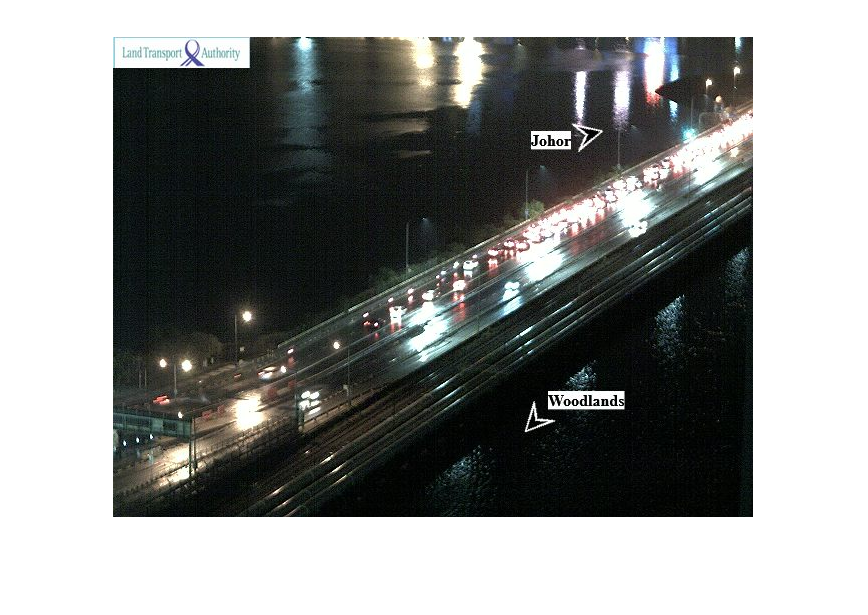

id = "2701";
w1=strcmp(string(cell2mat(w(:,4))),id);
imshow(imread(r.items.cameras(w1).image))

wmmarker(r.items.cameras(w1).location.latitude,r.items.cameras(w1).location.longitude);

### Save all the Images

Interval : 15 minutes

Save all images in Jan with interval 15 minutes

%create new folder
try
     mkdir dataset
     cd dataset
     mkdir 2701
     mkdir 2702
catch ME
     fprintf("Folders(2701 & 2702) are available")
end

cd("..")

for day=1:1:31
    for hour=0:1:23
        for minutes=0:15:45
            r=webread(sprintf('https://api.data.gov.sg/v1/transport/traffic-images?date_time=2020-02-%02dT%02d:%02d:01',day,hour,minutes));
            w=struct2cell(r.items.cameras)';
            w1=strcmp(string(cell2mat(w(:,4))),"2701");
            w2=strcmp(string(cell2mat(w(:,4))),"2702");
            %save to the folder 
            websave(sprintf('dataset/2701/Jan_2701_%02dT%02d_%02d_01.jpg',day,hour,minutes), r.items.cameras(w1).image);
            websave(sprintf('dataset/2702/Jan_2701_%02dT%02d_%02d_01.jpg',day,hour,minutes), r.items.cameras(w1).image);
        end
    end
end